Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Chromaticity of a FODO lattice (Section 3.4.1)

Volker Ziemann, 211124, CC-BY-SA-4.0

In this example we calculate the horizontal chromaticity of a somewhat contrived (no dipoles) ring made of 20 FODO cells.

We use the 2D software and define a FODO cell as in previous examples 

clear
addpath ./2D
F=2.2   % Slider for the focal length of the quadrupoles

F = 2.2000

fodo=[ 1,  5,  0.2,  0;   
	     2,  1,  0.0, -F;   
	     1, 10,  0.2,  0; 
	     2,  1,  0.0,  F;   
       1,  5,  0.2,  0]; 
beamline=fodo;

First we can calculate the transfer matrices with `calcmat()`, define the matrix Rturn, whch is the transfer matrix fromstart to end of the cell, and determine the phase advance of the cell $Q$ in units of $2\pi$ and the periodic Twiss parameters $\alpha_0,\beta_0$, and $\gamma_0$. And from those we cosntruct the beam matrix $\sigma_0$ which we later use to propagate the Twiss parameters through the ring.

[Racc,spos,nmat,nlines]=calcmat(beamline);
Rturn=Racc(:,:,end);
[Q,alpha0,beta0,gamma0]=R2beta(Rturn);
sigma0=[beta0, -alpha0; -alpha0,gamma0];

Next, we construct the beamline made of 20 FODO cells and calculate all transfer matrices with `calcmat()`.

beamline=repmat(fodo,20,1);  % 20 FODO cells
[Racc,spos,nmat,nlines]=calcmat(beamline);

Having prepared the beam matrix $\sigma_0$ with the Twiss parameters and all transfer matrices, we use Equation 3.43 to propagate the Twiss parameters through the ring. At each position, labeled by the loop index `k`, we store the value of the beta function in the previously allocated array `beta`. Once the loop completes, we plot the beta function and annotate the axes. 

beta=zeros(nmat,1);  % allocate space to store beta functions
for k=1:nmat
   sigma=Racc(:,:,k)*sigma0*Racc(:,:,k)';  % eq. 3.43
   beta(k)=sigma(1,1);
end
plot(spos,beta,'k');
xlabel(' s[m]'); ylabel('\beta_x [m]')
axis([0,spos(end),0,1.05*max(beta)])

Finally we calculate the chromaticity $Q'_x$ from Equation 3.87. To do  so we need to loop over all segments in the beamline and add $-\beta/4\pi f$ in each quadrupole. Once the loop completes, we report the tune of the ring, which is 20 times the tune of a cell, and the chromaticity in the title bar of the plot.

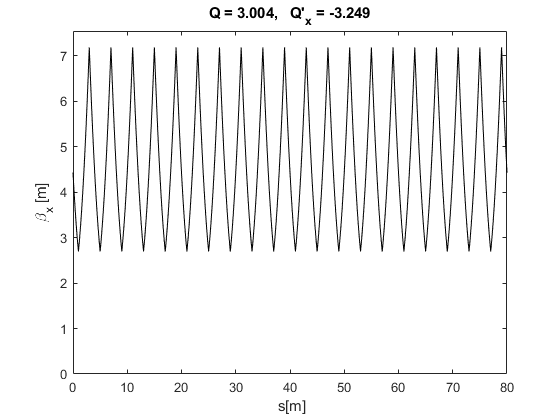

Chomaticity=0;     % initialize to zero
ic=1;                          
for line=1:nlines                
  for seg=1:beamline(line,2)
    ic=ic+1;
    if beamline(line,1)==2    % quadrupole found
      Chomaticity=Chomaticity-beta(ic)/(4*pi*beamline(line,4));  % eq. 3.87
    end
  end
end
title(['Q = ',num2str(20*Q,'%6.3f'),',   Q''_x = ' num2str(Chomaticity,4)])

And now you can play with the slider to change the focal length F of the quadrupoles so see how stronger focussing quadrupoles increase both the tune and the chromaticity.